Jireh Diboto-Mofa

Lab 9 // BMEN 1400

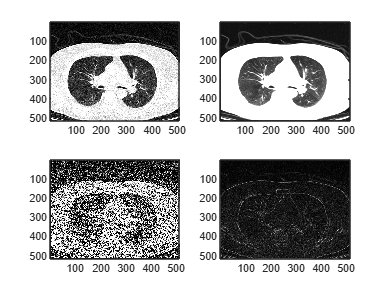

Lungpic = imread('LungCT.tif') ;
%Reading the image and storing it as in an array.

lowpass_filter = [ 1 1 1 1 1 ; 1 2 2 2 1 ; 1 2 3 2 1 ; 1 2 2 2 1 ; 1 1 1 1 1] /25 ; 
%higher values in the center for a brighter image 

highpass_filter = [ -1 -1 -1 ; -1 9 -1 ; -1 -1 -1] ; 
%Gives a smaller number in the center and negative values around the edges to emphasize the center of the image, hence 'sharpening' it

Kx = [0 0 0 ; -1 0 1 ; 0 0 0] * 0.5 ;
Ky = [0 -1 0 ; 0 0 0 ; 0 1 0] * 0.5 ;
%Addressing a number to each position except for edges

edgex = conv2(Kx,double(Lungpic)) ;
edgey = conv2(Ky,double(Lungpic)) ;
%Convuluting the edges

smoothed_image = conv2(lowpass_filter,double(Lungpic)) ;
sharp_image = conv2(highpass_filter,double(Lungpic)) ;
%Applying the highpass and lowpass filters


Edge_detect = sqrt(edgex.^2 + edgey.^2) ;
%Formula for magnitude

figure

   subplot(2,2,1) 
   % first 2 values is xy axes, last value is figure number within the subplot
    image(double(Lungpic))
        colormap(gray(2500)) 
        %Colormap command is to map a specific color onto an entire image, the number is the intensity

   subplot(2,2,2)
    image(smoothed_image)
     colormap(gray(3000))

   subplot(2,2,3)
    image(sharp_image)
     colormap(gray(8000))

   subplot(2,2,4)
    image(Edge_detect)
     colormap(gray(1000))